# Skin Lesion Classification via CNN Transfer Learning

Last updated: October 7, 2021

#### Load dataset

dataLocation = "Dataset/ISIC_2019_Training_Input"

dataLocation = "Dataset/ISIC_2019_Training_Input"

labelsLocation = "Dataset/groundtruth_categorical.csv"

labelsLocation = "Dataset/groundtruth_categorical.csv"

Create a datastore for the raw images

image_datastore = imageDatastore(dataLocation);
num_images = length(image_datastore.Files);

Import ground truth labels

groundtruth = readtable(labelsLocation);
image_datastore.Labels = categorical(groundtruth.category(1:num_images));
labelCounts = countEachLabel(image_datastore)

labelCounts = 8×2 table
             Label             Count
    _______________________    _____

    Actinic keratosis            867
    Basal cell carcinoma        3323
    Benign keratosis            2624
    Dermatofibroma               239
    Melanocytic nevus          12875
    Melanoma                    4522
    Squamous cell carcinoma      628
    Vascular lesion              253


minCategoryImageCount = min(labelCounts.Count);

Display some images with their labels

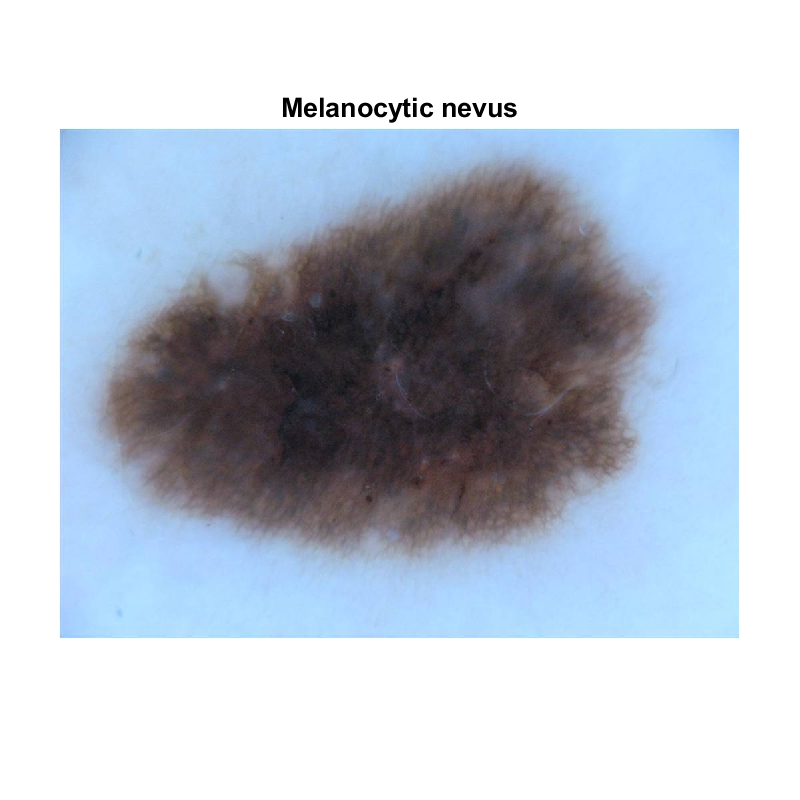

sample_idx = 1;
imshow(readimage(image_datastore, sample_idx));
title(image_datastore.Labels(sample_idx), 'FontSize', 20);

#### Split dataset into training set, validation set, and test set.

[trainImds, valImds] = splitEachLabel(image_datastore, 0.8, 'randomized');

### Balance training set by oversampling underrepresented classes

trainingLabelCounts = countEachLabel(trainImds);
targetLabelCount = max(trainingLabelCounts.Count);
balTrainImds = oversampleDataset(trainImds, targetLabelCount);
labelCounts = countEachLabel(balTrainImds)

labelCounts = 8×2 table
             Label             Count
    _______________________    _____

    Actinic keratosis          10300
    Basal cell carcinoma       10300
    Benign keratosis           10300
    Dermatofibroma             10300
    Melanocytic nevus          10300
    Melanoma                   10300
    Squamous cell carcinoma    10300
    Vascular lesion            10300


#### Augment images and Resize images to work with GoogLeNet

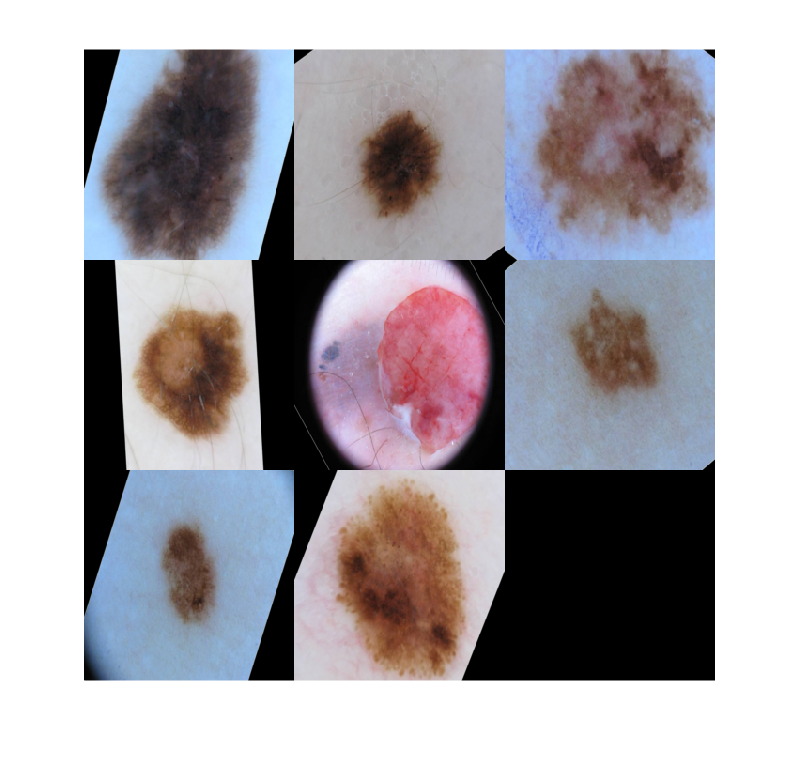

augmenter = imageDataAugmenter("RandXReflection", true, "RandYReflection", true, "RandRotation", [-180 180], "RandScale", [0.8 1.5]);

trainds = augmentedImageDatastore([224,224], balTrainImds,"DataAugmentation",augmenter);
minibatch = preview(trainds);
imshow(imtile(minibatch.input));


valds = augmentedImageDatastore([224,224], valImds);

### Import and modify pretrained Neural Network

net = googlenet;
lgraph = layerGraph(net);

newFc = fullyConnectedLayer(numel(labelCounts.Label),"Name","new_fc");
lgraph = replaceLayer(lgraph,"loss3-classifier",newFc);

#### Implement weighted cross-entropy loss to address imbalanced dataset

classWeights = max(labelCounts.Count)* ones(1,numel(labelCounts.Label)) ./ labelCounts.Count'

classWeights =      1     1     1     1     1     1     1     1



newOut = classificationLayer("Name","new_out", "ClassWeights", classWeights, "Classes", labelCounts.Label);
lgraph = replaceLayer(lgraph,"output",newOut);

### Set training options

Stochastic Gradient Descent with Momentum

Learning rate = 0.001

miniBatchSize = 64;
validationFrequency = floor((numel(trainds.Files)/miniBatchSize)/3);
options = trainingOptions("sgdm", ...
    "InitialLearnRate", 0.001, ...
    'MiniBatchSize',128/2, ...
    'MaxEpochs', 30, ...
    'Plots','training-progress',"L2Regularization", 1e-2, ... 
    "ValidationData", valds, "ValidationFrequency",validationFrequency, ...
    "OutputNetwork","best-validation-loss", "ValidationPatience", 10);

### Train the neural network

Training on single GPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:37 |       10.94% |       28.75% |       3.8238 |       2.3327 |          0.0010 |
|       1 |          50 |       00:01:25 |       29.69% |              |       1.8939 |              |          0.0010 |
|       1 |         100 |       00:02:14 |       48.44% |              |       1.3815 |              |          0.0010 |
|       1 |         150 |       00:03:04 |       45.31% |              |       1.4675 |   

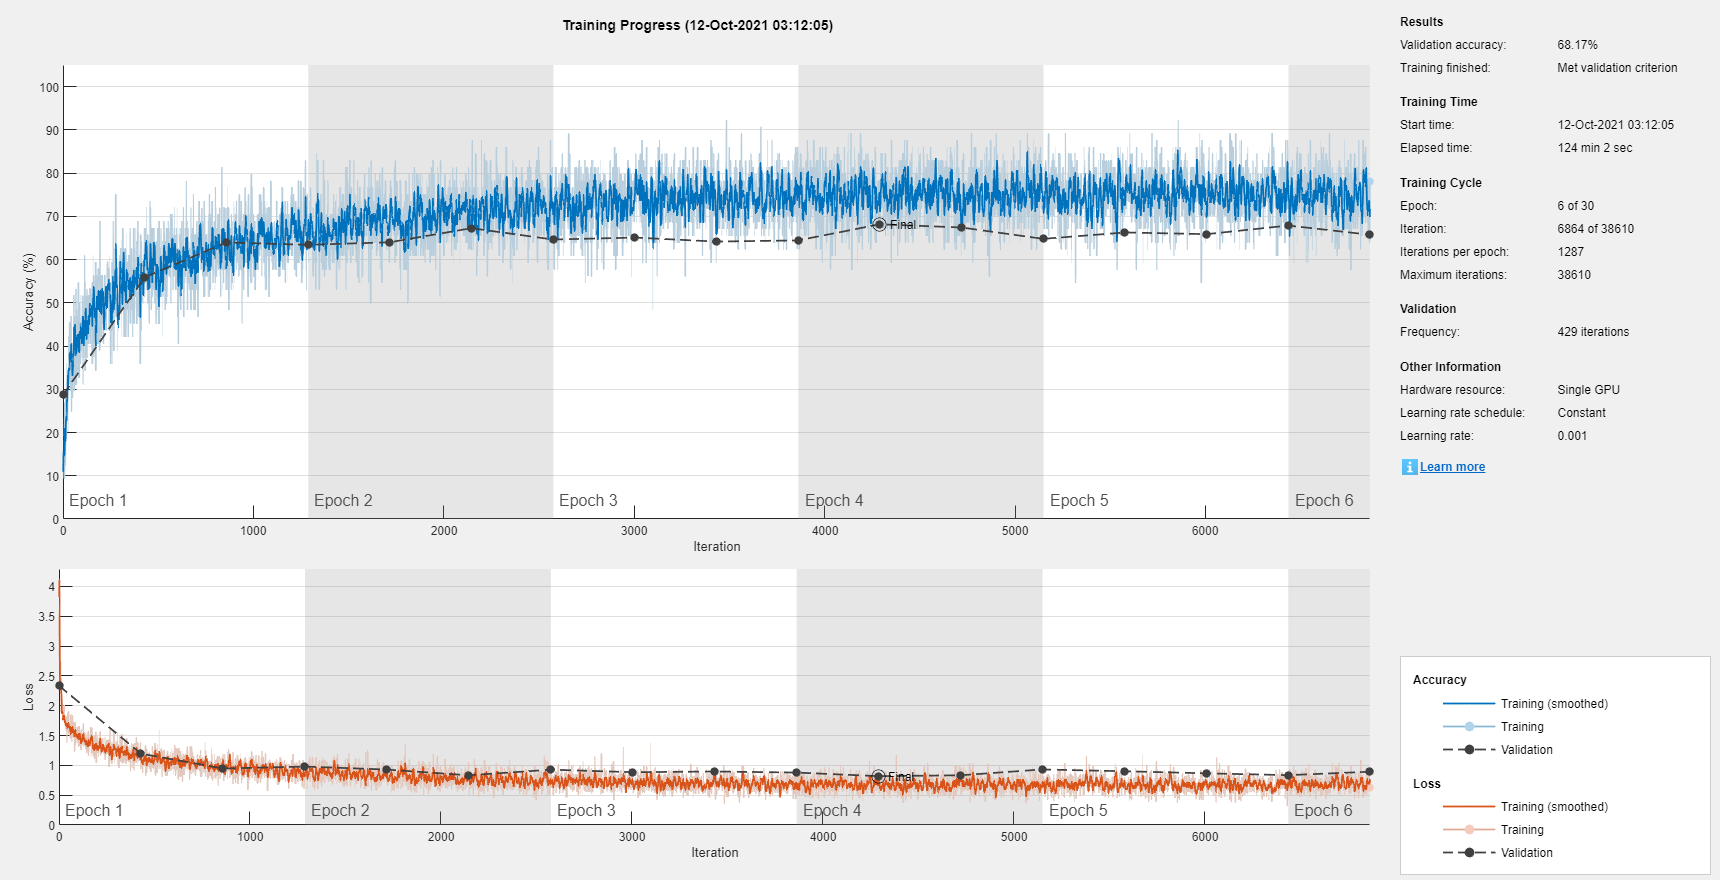

lesionNet = trainNetwork(trainds, lgraph, options);

Save trained model to device

save lesionNet_prev.mat lesionNet;

#### Evaluate network on Validation set

preds = classify(lesionNet, valds);
valTrue = valImds.Labels;
valAccuracy = nnz(preds == valTrue)/numel(preds)

valAccuracy = 0.6817

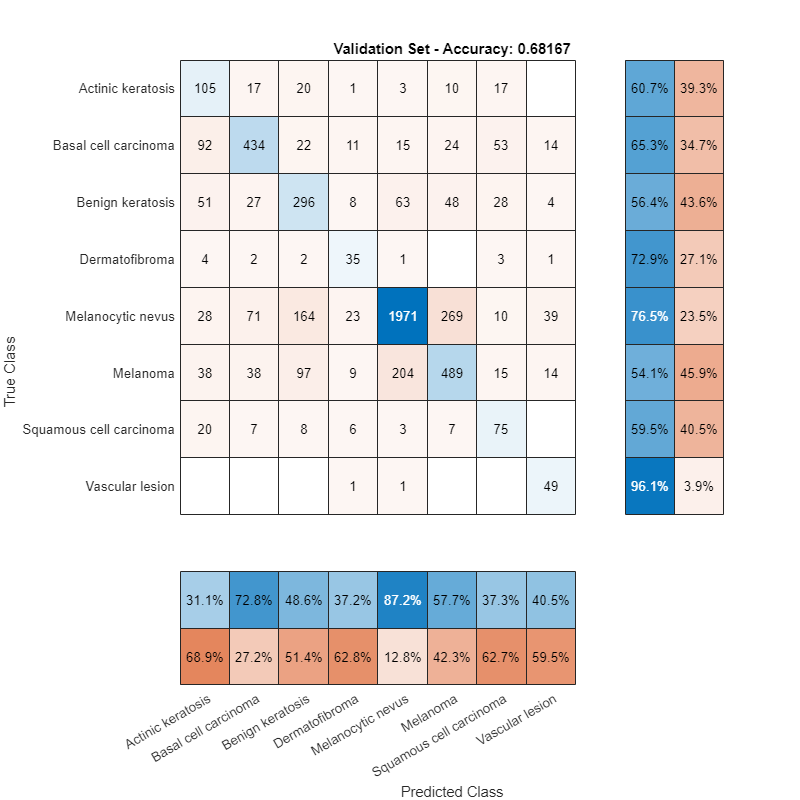

confusionchart(valTrue, preds, 'RowSummary','row-normalized', 'ColumnSummary','column-normalized','Title',"Validation Set - Accuracy: " + string(valAccuracy));

### Visualize failed predictions

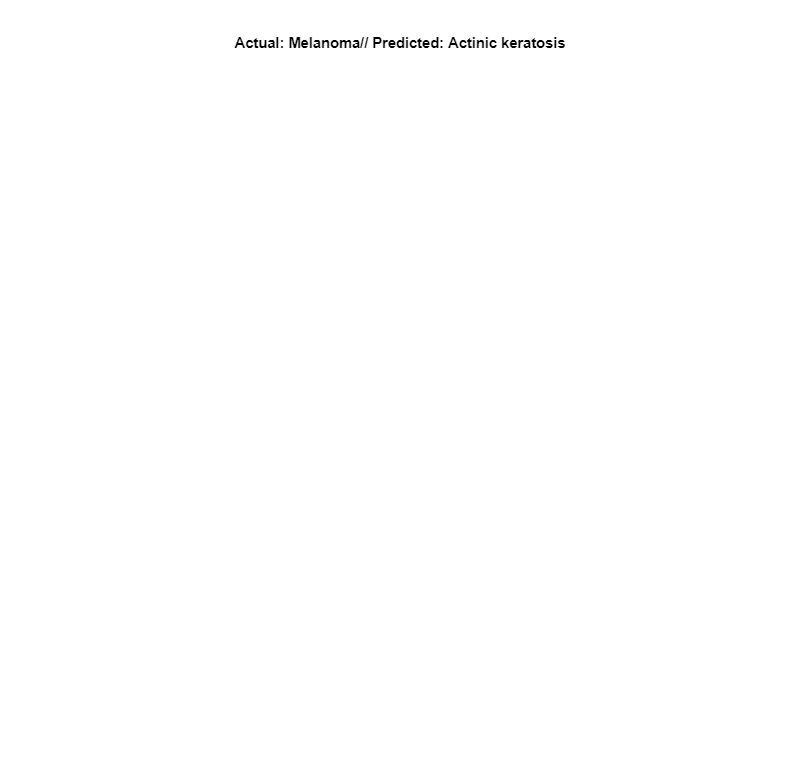

failedPredictions = find(preds~=valTrue);
num_fail = numel(failedPredictions);
failedSample = 887;
if ~isempty(failedPredictions)
    imshow(readimage(valImds,failedPredictions(failedSample)), 'InitialMagnification', 100);
    title("Actual: " + string(valTrue(failedPredictions(failedSample))) + "// Predicted: " + string(preds(failedPredictions(failedSample))))
end

### Visualize correct predictions

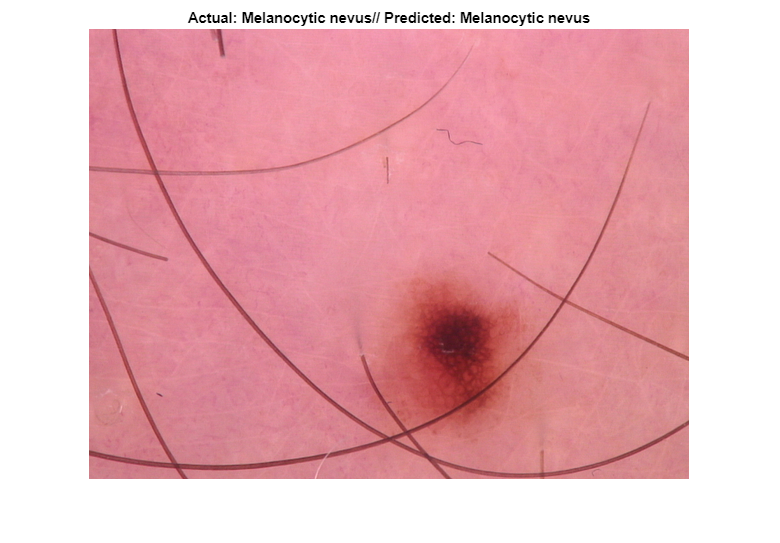

correctPredictions = find(preds==valTrue);
num_correct = numel(correctPredictions);
correctSample = 1622;
if ~isempty(correctPredictions)
    imshow(readimage(valImds,correctPredictions(correctSample)), 'InitialMagnification', 100);
    title("Actual: " + string(valTrue(correctPredictions(correctSample))) + "// Predicted: " + string(preds(correctPredictions(correctSample))))
end